# **Matlab Stimulation**

% electrical constants and derived quantities for typical 
% mammalian dendrite

% Dimensions of compartments

d1 = 75e-4; 			% cm
d21 = 30e-4; 			% cm
d22 = 15e-4; 			% cm


l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

## Question 03

x=A\b;
disp(x);

    0.0007
    0.0000
    0.0011
   -0.0000
    0.0011
   -0.0000



## Question 04

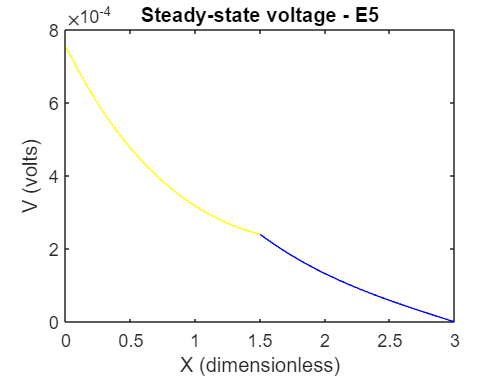

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$\text{The red line is not visible in the diagram, indicating it is either equal to or very close to the blue line. }\\ \text{ Since the yellow line (the parent branch's membrane potential) does not affect the daughter branches, }\\ \text{it is concluded that the red and blue lines are equal.}\\  \text{Therefore, the steady state voltage profiles of the two daughter branches are identical. } \\ \text{The code also supports this conclusion by plotting the red and blue lines, with the red line being hidden by the blue line, }\\ \text{confirming their equality and the identical voltage profiles of the branches. }\\ \text{Additionally, it mentions that the plots of and the plots of seem to be identical, } \\ \text{which further supports the conclusion. As a result, the steady-state voltage profile through the two daughter branches is equal.}$$


## Question 05

A_a=A;
b_a=b;


$$
\text{(i)} \quad \left( \frac{d}{dX} V_{21} \right)_{X= L_{21}}=0 \\
- A_{21} e^{-L_{21}} + B_{21} e^{-L_{21}} =0  \quad \longrightarrow \quad (2'')\\

\text{Sealed End at} \,V_{21}\\
\text{Killed End at} \,V_{22}\\$$


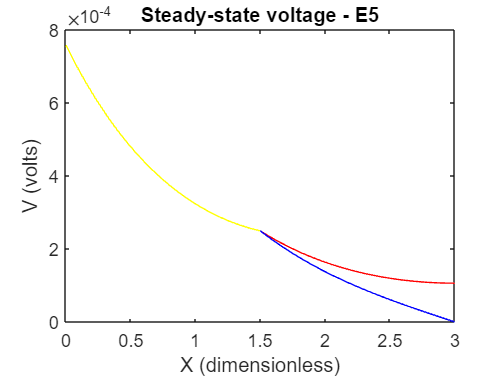


A_a(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$\text{(ii)} \quad \left( \frac{d}{dX} V_{22} \right)_{X = L_{22}}=0 \\
- A_{22} e^{-L_{22}} + B_{22} e^{-L_{22}} = 0\quad \longrightarrow \quad (3'') \\

\text{Sealed End at} \,V_{21}\\
\text{Sealed End at} \,V_{22}\\$$


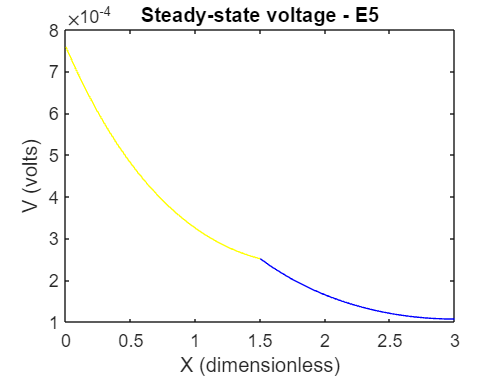

A_a(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$\text{(iii)} \quad \left( \frac{d}{dX} V_{1} \right)_{X= 0} =0\\
   - A_{1} + B_{1}  \quad \longrightarrow \quad (1'')=0 \\
  \quad \left( \frac{d}{dX} V_{1} \right)_{X= L_{1}} =  rl21*Iapp\\
- A_{21} e^{-L_{21}} + B_{21} e^{-L_{21}} =0 \quad \longrightarrow \quad (2'')\\

\text{Sealed End at} \,V_{21}\\
\text{Killed End at} \,V_{22}\\
\text{Current applied at node passes through the 21 branch only}\\
\text{Positive Voltage gradient at end 21}$$


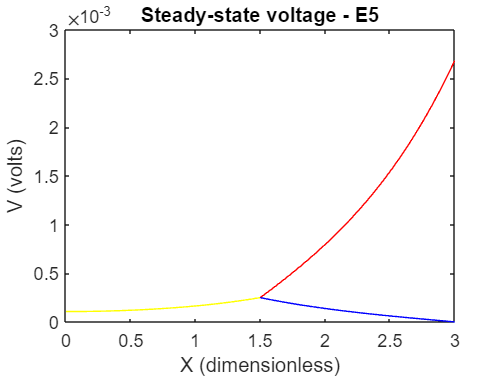

b(1) = 0; b(2) = rl21*iapp;
A_a(3,:) = A(3,:);
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

 
$$\text{(iv)} \quad \left( \frac{d}{dX} V_{1} \right)_{X= L_{1}} =  rl22*Iapp\\
- A_{22} e^{-L_{22}} + B_{22} e^{-L_{22}} =0 \quad \longrightarrow \quad (3'') \\
\text{Sealed End at} \,V_{21}\\
\text{Sealed End at} \,V_{22}\\
\text{Current applied at node passes through the 21 and 22 branch, but the diameters of the branches are different}\\
\text{Positive Voltage gradient at both ends}


$$


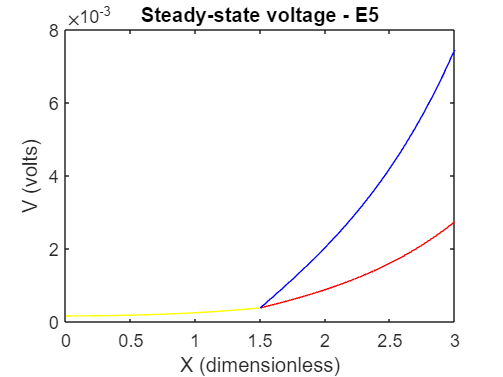

b(3) = rl22*iapp;
A_a(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_a\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$\[
\text{The positive right-hand sides of } \left( \frac{d}{dX} V_{21} \right)_{X=L_{21}} \text{ and } \left( \frac{d}{dX} V_{22} \right)_{X=L_{22}}\\ \text{ in 2(c) and 2(d) indicate that the membrane voltage gradient is positive at the rightmost nodes of the daughter branches.}\\
\text{ This means the daughter branches transmit an electrical impulse to another neuron or branch.}\\ \text{ The increase in membrane voltage at these rightmost nodes causes the voltage gradient to be positive, }\\ \text{ensuring efficient electrical impulse transmission from the parent branch to the daughter branches.}
\]

$$


## Question 06

% Dimensions of compartments

d21 = 47.2470e-4;	     % E9 cm
d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';


$$\text{Sealed End at} \,V_{21}\\
\text{Sealed End at} \,V_{22}\\
\text{Current applied at terminal X=0}\\
\text{Diameter of both branch are equal}$$


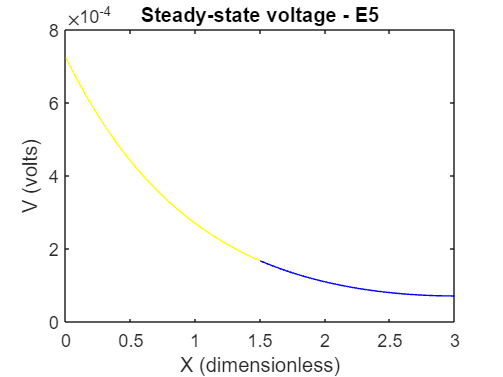

A_1=A;
A_1(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
A_1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_1\b;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$\text{Sealed End at} \,V_{21}\\
\text{Sealed End at} \,V_{22}\\
\text{Current applied at node passes through the 21 and 22 branch, but the diameters of the branches are equal}\\
\text{Positive voltage gradient at both ends}$$
 

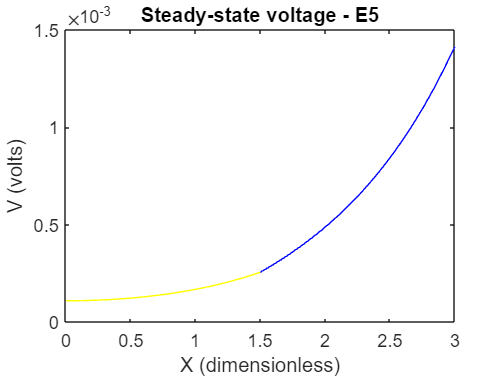

A_2=A;
b_2=b;
A_2(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
A_2(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
b_2(1) = 0; b_2(2) = rl21*iapp;
b_2(3) = rl22*iapp;
x_a=A_2\b_2;
y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');


$$
\text{The given image explains the significance of certain properties observed in graphs labeled 2(c) and 2(d).} \\
 \text{Both graphs exhibit a continuously differentiable voltage profile, which allows smooth transmission of} \\
\text{electrical impulses from the parent branch to the daughter branches.}\\
\text{Smooth transitions due to identical properties of both ends} \\ \\

\textbf{For graph 2(c):} \\
\text{Both daughter branches have \textbf{sealed ends}, meaning the (zero axial current)} \\
\text{at their terminals. Since the structural and electrical parameters (diameter, length, resistivity)} \\
\text{of both branches are identical, they experience identical voltage drops, causing the voltage curves} \\
\text{of both branches to \textbf{overlap} completely.}
\text{In sealed end with zero axial no matter with structural parameter potential difference same} \\ \\

\textbf{For graph 2(d):} \\
\text{Both daughter branches are instead \textbf{sealed at their ends} (Positive Voltage gradient), but they still} \\
\text{have identical electrical properties (same diameter, same resistance, same length).} \\
\text{Due to this perfect symmetry, the resulting potential difference along both branches is the same,} \\
\text{leading again to \textbf{overlapping voltage profiles} despite the change in boundary condition.} \\
\text{In conclusion, the overlap of voltage curves in both 2(c) and 2(d) is due to the identical properties} \\
\text{of the daughter branches, and in 2(c), also due to both ends being sealed with zero axial current. These observations are} \\
\text{complementary and reinforce that symmetry in structure and boundary conditions leads to equal} \\
\text{voltage behavior across branches.}



$$
